% Define the state-space matrices
A = [-0.254 0 -1 0.182;
     -16.02 -8.40 2.19 0;
     4.488 -0.350 -0.760 0;
     0 1 0 0];

B = [0; -28.916; -0.244; 0];
C = [0 0 0 1];
D = [0];

% Create the state-space system
System = ss(A, B, C, D);

% Convert to transfer function
G = tf(System);

% Display the transfer function
disp('Transfer Function G(s):');

Transfer Function G(s):


G


G =
 
           -28.92 s^2 - 29.86 s - 139.4
  ----------------------------------------------
  s^4 + 9.414 s^3 + 13.97 s^2 + 48.04 s + 0.4271
 
Continuous-time transfer function.
Model Properties


% Assuming G is already defined as the transfer function
Zeros = zero(G);  % Calculate zeros of G(s)
Poles = pole(G);  % Calculate poles of G(s)

% Display the zeros and poles
disp('Zeros:');

Zeros:


disp(Zeros);

  -0.5162 + 2.1341i
  -0.5162 - 2.1341i



disp('Poles:');

Poles:


disp(Poles)

  -8.4328 + 0.0000i
  -0.4862 + 2.3336i
  -0.4862 - 2.3336i
  -0.0089 + 0.0000i



inf = stepinfo(G);  % Get step response info
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(inf);

         RiseTime: 246.4959
    TransientTime: 438.9933
     SettlingTime: 438.9933
      SettlingMin: -326.2062
      SettlingMax: -295.2278
        Overshoot: 0
       Undershoot: 0
             Peak: 326.2062
         PeakTime: 821.5237



% Check stability
if all(real(Poles) < 0)  % Added closing parenthesis
    disp('The system is dynamically stable.');
else
    disp('The system is not stable.');
end

The system is dynamically stable.


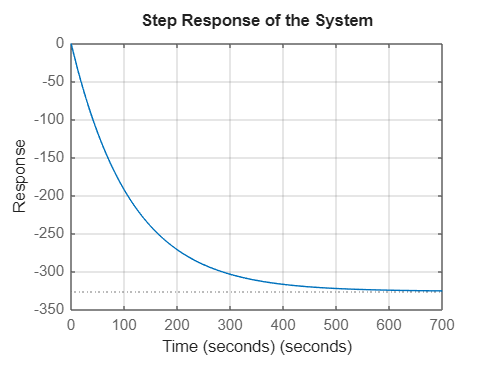

% Generate the step response
figure;                  % Create a new figure window
step(System);           % Plot the step response
title('Step Response of the System'); % Add a title
xlabel('Time (seconds)'); % Label for x-axis
ylabel('Response');       % Label for y-axis
grid on;                 % Add a grid to the plot 

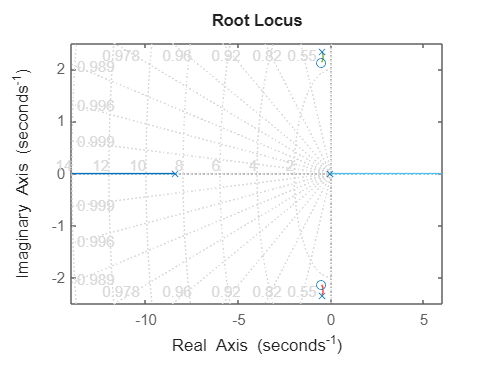

rlocus(G);
grid on; % Adds a grid to the plot for better visualization
title('Root Locus');

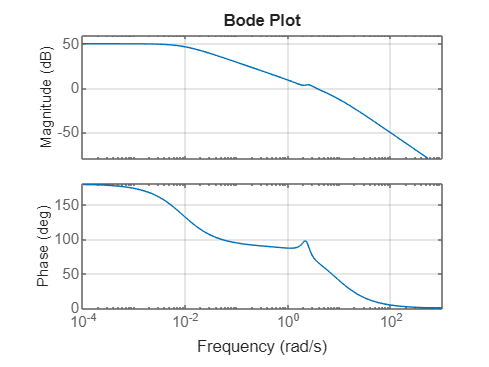

bode(G);
grid on;
title('Bode Plot');


% Calculate the controllability matrix
u = ctrb(A, B);

% Determine the length of A
n = length(A);

% Determine the rank of the controllability matrix
rang = rank(u);

% Check controllability
if rang == n
    disp('The object is controllable.');
else
    disp('The object is not controllable.');
end

The object is controllable.


pidTuner(G, 'PID');


% Define the PID parameters
Kp = -0.68572;  % Proportional gain
Ki = -0.34403;  % Integral gain
Kd = -0.13793;  % Derivative gain

% Create the PID controller
PID_Controller = pid(Kp, Ki, Kd);

% Assuming 'System' is the transfer function or state-space model you've defined
% Create the closed-loop transfer function
Gclosed = feedback(PID_Controller * System, 1);

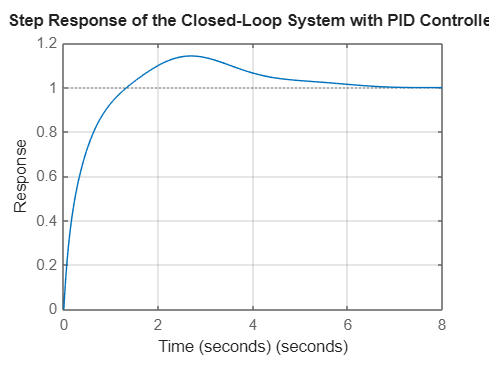

% Step response of the closed-loop system
figure;
step(Gclosed);
title('Step Response of the Closed-Loop System with PID Controller');
xlabel('Time (seconds)');
ylabel('Response');
grid on;


% Display step response characteristics
info = stepinfo(Gclosed);  % Get step response info
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.8617
    TransientTime: 5.7040
     SettlingTime: 5.7040
      SettlingMin: 0.9014
      SettlingMax: 1.1427
        Overshoot: 14.2705
       Undershoot: 0
             Peak: 1.1427
         PeakTime: 2.6905



% Assuming Gclosed is your closed-loop transfer function
[Gm, Pm, Wcg, Wcp] = margin(Gclosed);

disp(['Gain Margin: ', num2str(Gm), ' dB']);

Gain Margin: Inf dB


disp(['Phase Margin: ', num2str(Pm), ' degrees']);

Phase Margin: 147.621 degrees


disp(['Gain Crossover Frequency: ', num2str(Wcg), ' rad/s']);

Gain Crossover Frequency: NaN rad/s


disp(['Phase Crossover Frequency: ', num2str(Wcp), ' rad/s']);

Phase Crossover Frequency: 1.0995 rad/s


Gclosed


Gclosed =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7
   x1         0         0         0         0         0         0         1
   x2         0         1         0         0         0         0         0
   x3         0         0         1         0         0         0        -1
   x4         0         0         0    -0.254         0        -1     0.182
   x5    -9.948    -3.988         0    -16.02      -8.4      2.19    -19.83
   x6  -0.08394  -0.03365         0     4.488     -0.35     -0.76   -0.1673
   x7         0         0         0         0         1         0         0
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4       0
   x5  -28.92
   x6  -0.244
   x7       0
 
  C = 
            x1       x2       x3       x4       x5       x6       x7
   y1   -0.344  -0.1379        0        0        0        0  -0.6857
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3  x4  x5  x6  x7
   x1   1   0   0   0   0   0   

% Define the A, B, C, and D matrices with uppercase names
E = [0 0 0 0 0 0 1; 
     0 1 0 0 0 0 0; 
     0 0 1 0 0 0 -1; 
     0 0 0 -0.254 0 -1 0.182; 
     -9.948 -3.988 0 -16.02 -8.4 2.19 -19.83; 
     -0.08394 -0.03365 0 4.488 -0.35 -0.76 -0.1673; 
     0 0 0 0 1 0 0];

F = [0; 0; 0; 0; -28.92; -0.244; 0];

G = [-0.344 -0.1379 0 0 0 0 -0.6857];

H = 0; % Assuming H (D) is a scalar

% Create state-space system
SYS_SS = ss(E, F, G, H);

% Convert to transfer function
G_CLOSED = tf(SYS_SS);

% Display the new closed-loop transfer function
disp('New Closed-Loop Transfer Function:');

New Closed-Loop Transfer Function:


G_CLOSED


G_CLOSED =
 
          19.83 s^3 + 30.42 s^2 + 105.9 s + 47.96
  --------------------------------------------------------
  s^5 + 9.414 s^4 + 33.8 s^3 + 78.46 s^2 + 106.3 s + 47.96
 
Continuous-time transfer function.
Model Properties


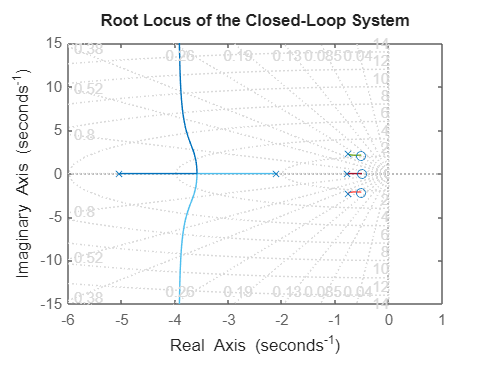

rlocus(G_CLOSED);
grid on; % Adds a grid to the plot for better visualization
title('Root Locus of the Closed-Loop System');

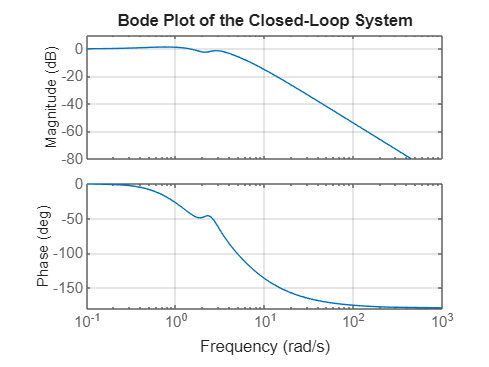

bode(G_CLOSED);
grid on;
title('Bode Plot of the Closed-Loop System');